clear;
col_tot = 100000;
row_tot = 1;
t_x = 1;
t_y = 1;


%% 对角化计算态密度
Disorder = 1;
epsilon = 0.05;
B_Field = 0;
if B_Field~=0
    H_sparse = get_Nearest_Square_Hopping_Sparse(col_tot, row_tot, t_x, t_y, [], B_Field);
else
    H_sparse = get_Nearest_Square_Hopping_Sparse(col_tot, row_tot, t_x, t_y);
end
% H_sparse = sparse(Lieb_2D_Hamiltonian_Real([0,0,0],1.3,0.7,0.7,row_tot,col_tot));

H_sparse = H_sparse + Disorder * (sprand(speye(size(H_sparse))) - 0.5 * speye(size(H_sparse)));
% H_sparse = sprand(col_tot*row_tot,col_tot * row_tot,1e-4);
tic;
% Eigv = eig(H_sparse);

% h = histogram(Eigv(:),5*col_tot,'Normalization','pdf');
% BinMax = max(h.Values,[],'all');

%% KPM计算态密度

N_randvec = 1;
N_moments = 1500;
N_points = 2 * N_moments;
% N_points = 300;
[H_tilde, a, b] = KPM_scaleHamiltonian(H_sparse);

% Kernel_Jackson = KPM_Kernel(N_moments, 'Jackson');

Moments = KPM_Moments_Spectrum(H_tilde, N_randvec, N_moments,'gpu');

ans = "The computer has gpu, for matrix larger than 500 the gpu is initiated"


toc;

历时 3.067547 秒。


Moments_Kernel = KPM_Kernel_Correction(Moments, N_moments, 'Jackson');

% omega_dct = linspace(-1+epsilon,1-epsilon,N_points);
% DOS = zeros(1,length(omega_dct));
% parfor ii = 1:length(omega_dct)
%     DOS(ii) = (1/pi ./sqrt(1-omega_dct(ii).^2)) .*(Moments_Kernel*chebyshevT(0:N_moments-1,omega_dct(ii))');
% end

[omega_dct, DOS] = KPM_DCT(Moments_Kernel, N_points);
DOS = sqrt(length(Moments_Kernel)) * DOS;
omega = KPM_rescale(omega_dct, a, b);

% Normalize the DOS
% DOS = DOS / max(DOS,[],'all')*BinMax;

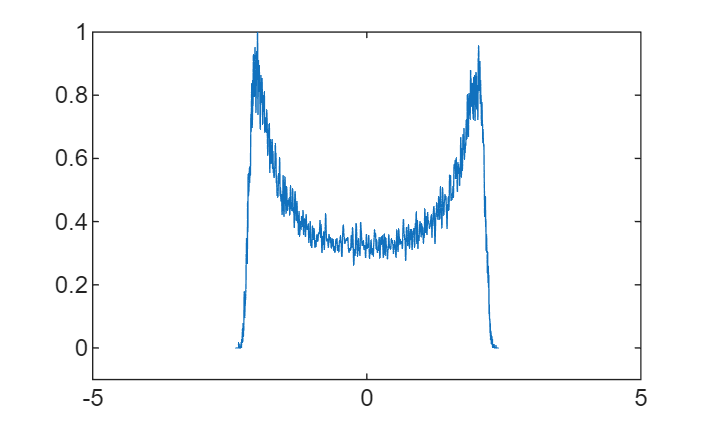

if B_Field~=0
    epsilon = 0;
    [kx_list, energy_band] = Hamiltonian_2D_Momentum(row_tot, epsilon, B_Field, t_x);
    
    subplot(1,2,2)
    % p = plot(kx_list,energy_band, kx_list, peakpos' * ones(1,length(kx_list)),'black--');
    p = plot(kx_list,energy_band);
    g = gca;
    title(['phi=',num2str(B_Field)]);
    xlabel('k_x')
    ylabel('E')
    subplot(1,2,1)
    plot(DOS/max(DOS,[],'all'), omega);
    axis([0,1,g.YLim])
    set(gca,'Clipping','Off')
    [~, loc] = findpeaks(DOS,'minpeakprominence',1);
    peakpos = omega(loc);
    for ii = 1:length(peakpos)
        h = line([0,3],[peakpos(ii),peakpos(ii)],'linestyle','--');
    end
else
    % hold on
    plot(omega, DOS/max(DOS,[],'all'))
    hold on
    % plot(omega, DOS)
    axis([-5,5,-1e-1,1])
    % 无磁场下解析计算对比
    
    hold on
    if row_tot ~= 1
        e=-4:0.015:4;
        % plot(e,BinMax*ellipke(sqrt(1-e.^2/16))/(max(ellipke(sqrt(1-e.^2/16)),[],'all')))
        plot(e, ellipke(sqrt(1-e.^2/16))/(max(ellipke(sqrt(1-e.^2/16)),[],'all')))
        hold off
        legend({"KPM","Analytical"})
    end
end


function [kx_list, energy_band] = Hamiltonian_2D_Momentum(Width, epsilon, phi, t)
    kx_step = 100;
    kx = [-pi,pi];
    kx_list = linspace(kx(1), kx(2),kx_step);
    energy_band = zeros(kx_step, Width);
    
    H_00 = epsilon * eye(Width) - t * diag(ones(1, Width-1),1) - t * diag(ones(1, Width-1),-1);
    H_01 = -t * diag(exp(1i * (1:Width) * phi));

    
    for ii = 1:length(kx_list)
        H = H_00 + exp(1i * kx_list(ii)) * H_01 + exp(-1i * kx_list(ii)) * H_01';
        energy_band(ii, :) = eig(H);
    end
end